# **Proyecto de sonido**

Grupo 06

Componentes: Alexis Hermida, Noa Cereixo, André Costas, José Luis Rodríguez

## 1. Introdución

Para la resolución de este proyecto, que tiene como objetivo la detección de componentes tonales en los archivos de audio de un baco de datos, se desarrollará la función ***detectar_tonales***. Dicha función precisará de un argumento de entrada con el nombre del archivo de audio cuya señal se desea analizar. A la salida, escribirá por pantalla "verdadero" si la señal contiene componentes tonales o "falso" en caso contrario y devolverá una estructura con la siguiente información sobre la señal procesada: frecuencia de muestreo, número total de muestras, duración y frecuencia fundamental (en el caso de que no contenga componentes tonales) o el número de ráfagas de energía y la longitud de las mismas (si contiene componentes tonales). Además,  mostrará esta información por pantalla en formato *tabla*, acompañada de la representación gráfica de la amplitud, de la magnitud y del espectograma de la señal y, en el caso de que contenga componentes tonales, del ancho de pulso de la envolvente del valor cuadrático medio. Por tanto, la signatura de la función se corresponde con la que sigue:

**info=detectar_tonales(nombrearchivo),**

siendo...

- ***info*** un argumento de tipo *struct* que contienen la información de la señal indicada anteriormente.

- ***nombrearchivo ***un argumento de tipo *character vector* que se corresponde con el nombre del archivo de audio que contiene la señal a analizar.

## 2. Banco de datos con archivos de audio

Para la evaluación del correcto funcionamiento de la función *detectar_tonales* se emplearán los archivos de audio contenidos en el **banco de datos** del proyecto. Este incluye un total de dieciséis archivos de audio (ocho de ellos con componentes totales y ocho sin componentes tonales), que se corresponden con los que se especificados en la siguiente tabla:

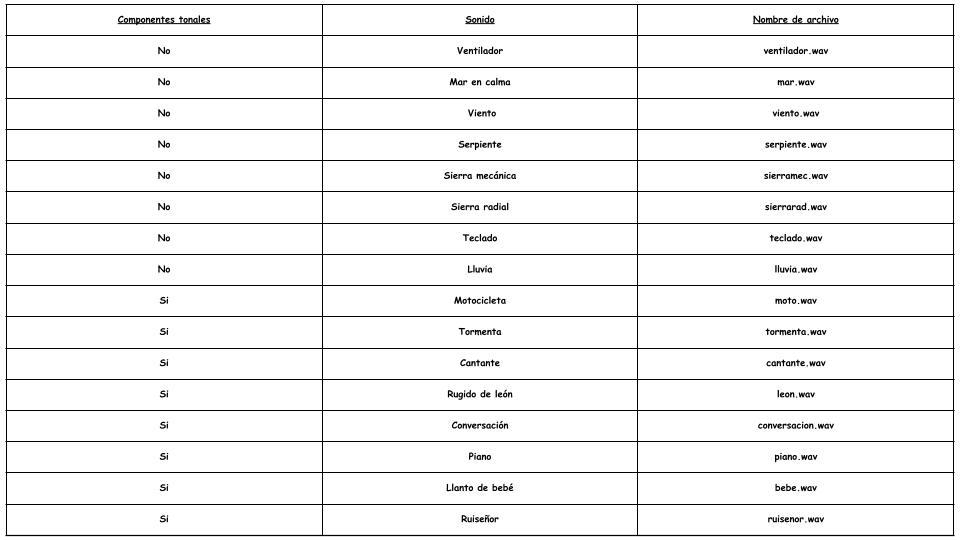

## 3. Detección de archivos de audio con y sin elementos tonales

En este apartado, se desarrollará el código para la evaluación de lo distintos archivos de audio listados anteriormente. Dicho código consistirá en la llamada de la función *detectar_tonales* pasando como argumento de entreda el nombre de los distintos archivos de la base de datos, que se encuentran almacenados en el array *NoTonales* o *Tonales*, según el resultado esperado al ejecutar la función.

En primer lugar, analizaremos los archivos que no contienen componentes tonales.

NoTonales=["ventilador.wav","mar.wav","viento.wav","serpiente.wav","sierramec.wav","sierrarad.wav","teclado.wav","lluvia.wav"];
for i=1:length(NoTonales);
    infoNoTonales.(erase(NoTonales(i),".wav"))=detectar_tonales(NoTonales(i));
end

'detectar_tonales' is not found in the current folder or on the MATLAB path, but exists in:
    C:\Users\noace\Desktop\2 GETT\2 cuatri\FSI\Practicas Sonido\ProyectoSonido

Change the MATLAB current folder or add its folder to the MATLAB path.

Ahora repetiremos el proceso con los archivos que sí presentan componentes tonales.

Tonales=["moto.wav","tormenta.wav","cantante.wav","leon.wav","conversacion.wav","piano.wav","bebe.wav","ruisenor.wav"];
for i=1:length(Tonales);
     infoTonales.(erase(Tonales(i),".wav"))=detectar_tonales(Tonales(i));
end

## 4. Conclusión

Esta clasificicación del sonido en función de la presencia o ausencia de componentes tonales resulta de gran utilidad a la hora de reducir los efectos nocivos del ruido en cualquier contexto. Para realizar esta reducción, se calcula el *nivel equivalente continuo*, que se define como el nivel de un ruido continuo que contiene la misma energía que el ruido medido. Sin embargo, resulta conveniente realizar algunas correciones sobre este nivel, teniendo en cuenta diferentes factores. Tras estas correcciones, obtenemos el *nivel de evaluación*, que se calcula mediante la siguiente expresión:

siendo Kt, el parámetro de corrección que evalua la molestia causada por los componentes tonales. Por tanto, la clasificación de los archivos de audio realizada en este proyecto constituye un estudio de gran interés en el tratamiento del ruido, especialmente, en zonas de carácter urbano como centros sanitarios, escolares, urbanizaciones, geriátricos...